bode_plot_options = bodeoptions();
bode_plot_options.Grid = 'on';
%bode_plot_options.PhaseWrapping = 'on';

# Plant

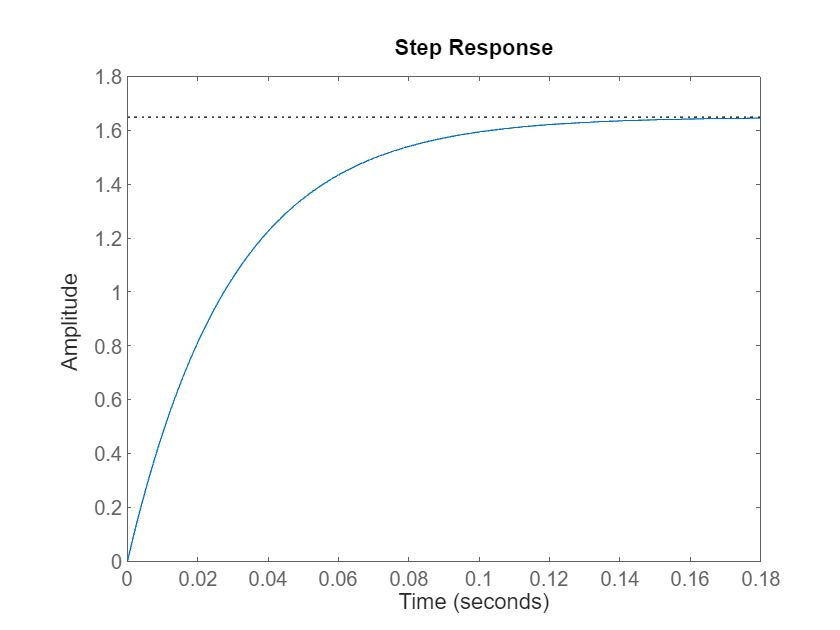

s = tf('s');
plant_tf = 55.99/(s+33.95);
step_response_parameters = stepinfo(plant_tf);
plant_ts = step_response_parameters.RiseTime;
step(plant_tf);

## Plant Discretization

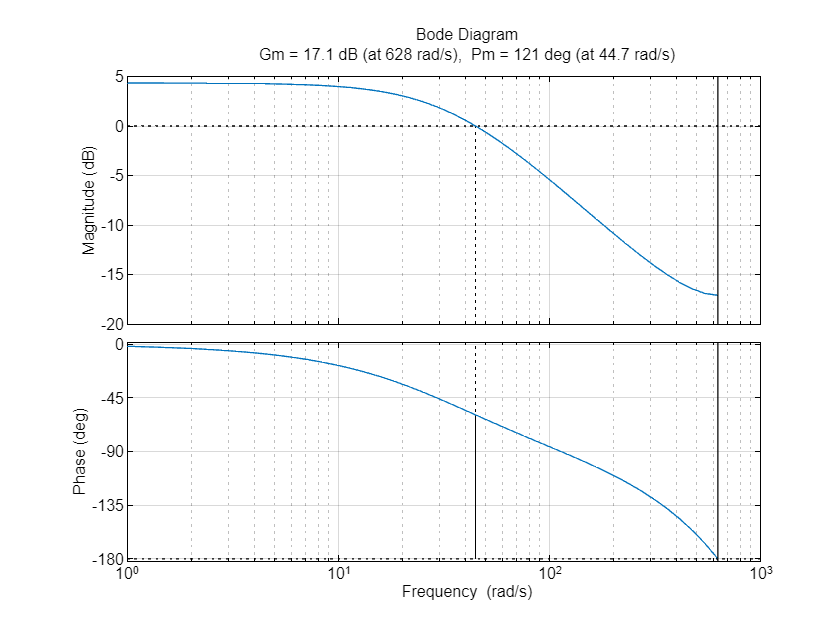

Ts = 0.005;
plant_tf_z = c2d(plant_tf,Ts,'zoh');
margin(plant_tf_z,bode_plot_options)

# Control Design

#### Parameters

Overshoot [Mp] <= 25%, Velocity Error [Ev] = 0, Pm >= 40°, Gm>=10dB

Controller type: 2 integrators and 2 lead compensators

## Integrators in z

2 integrators are assigned to get Ev=0, K is set to lower the negative phase margin and allow the lead compensators to fix the inestability created by the double integrators,

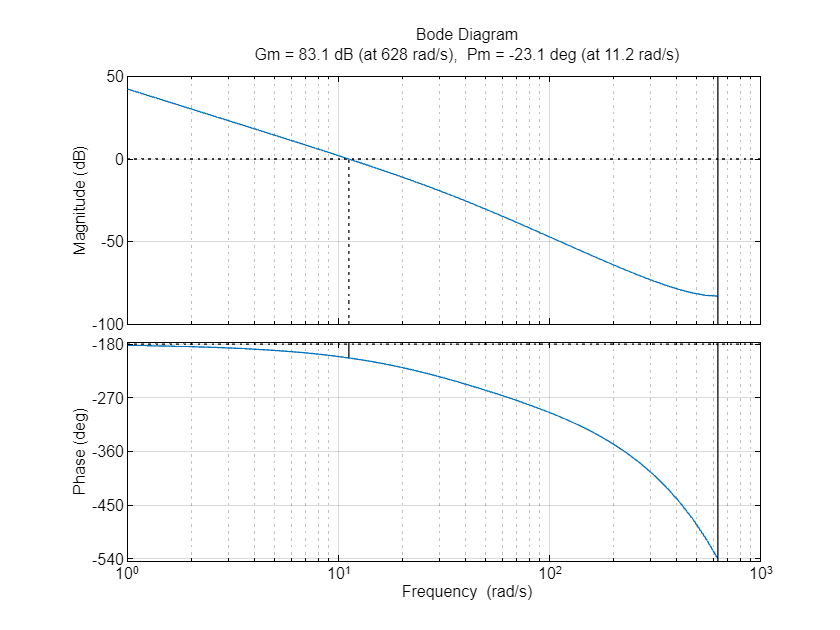

z = tf('z',0.005);
k = 0.002;
integ_ctrl_z = k/((z-1)^2);
integ_ctrl_plant_tf_z = series(integ_ctrl_z,plant_tf_z);
margin(integ_ctrl_plant_tf_z,bode_plot_options);

## W Transform for the plant plus the integrators

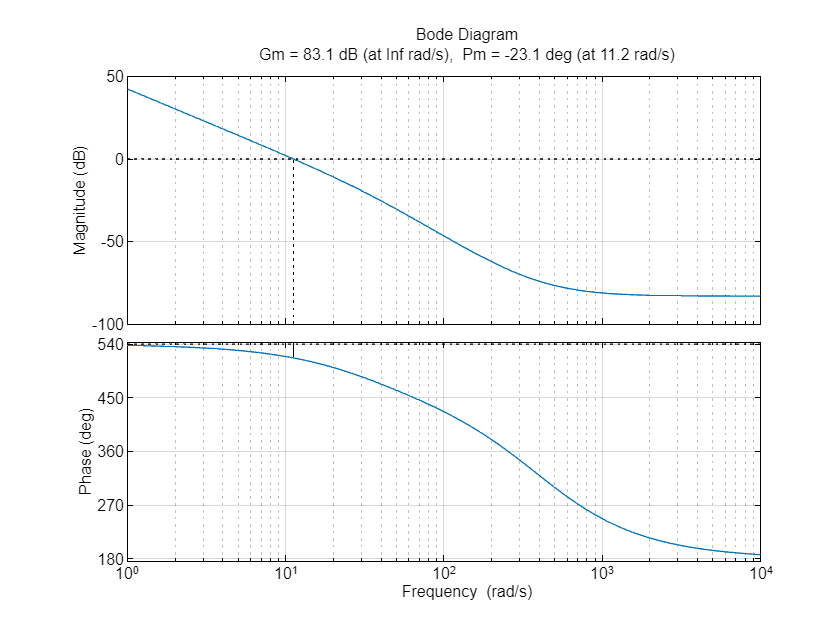

integ_ctrl_plant_tf_w = w_transform.z2w(integ_ctrl_plant_tf_z,Ts);
margin(integ_ctrl_plant_tf_w,bode_plot_options);

## First Lead Compensator in W

required_pm1 = 40+10-(-23.1);
b_1 = (1 + sind(required_pm1))/(1-sind(required_pm1));
disp("w1_crossover_gain: " + num2str(-10*log(b_1)));

w1_crossover_gain: -38.1355


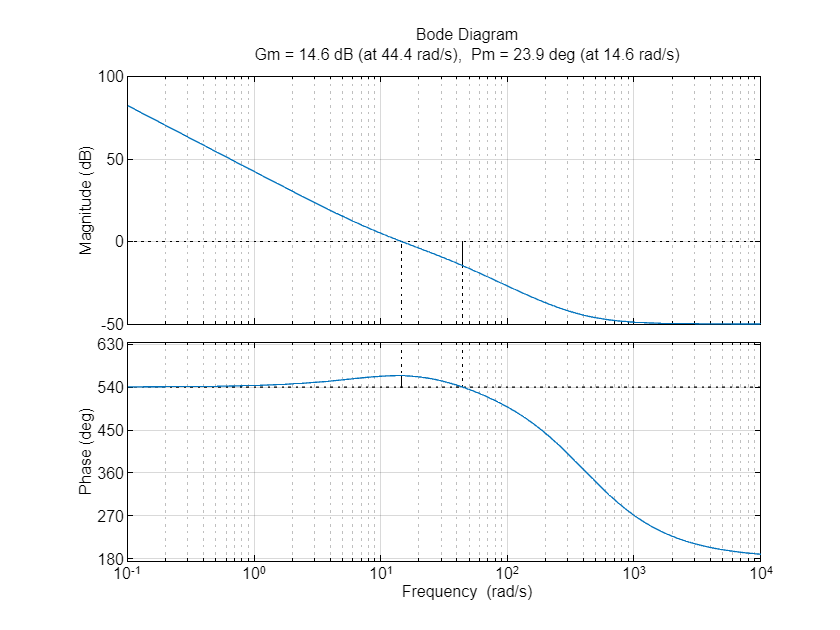

w1_crossover = 68;
T2_1=1/(sqrt(b_1)*w1_crossover);
lead_ctrl1_tf_w = (1+(b_1*T2_1*s))/(1+(T2_1*s));
margin(lead_ctrl1_tf_w*integ_ctrl_plant_tf_w,bode_plot_options);

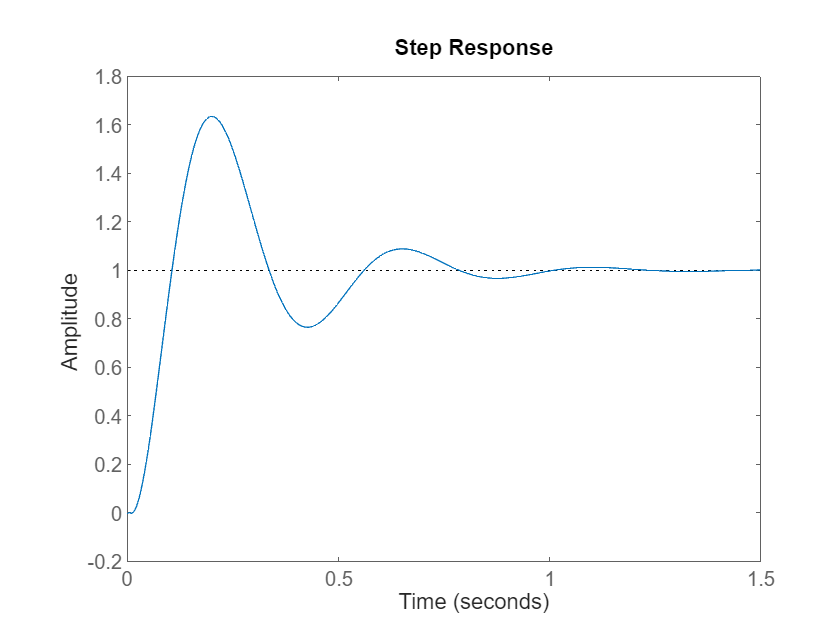

step(feedback(lead_ctrl1_tf_w*integ_ctrl_plant_tf_w,1));

## Second Lead Compensator in W

required_pm2 = 40+30-(23.9);
b_2 = (1 + sind(required_pm2))/(1-sind(required_pm2));
disp("w2_crossover_gain: " + num2str(-10*log(b_2)));

w2_crossover_gain: -18.1758


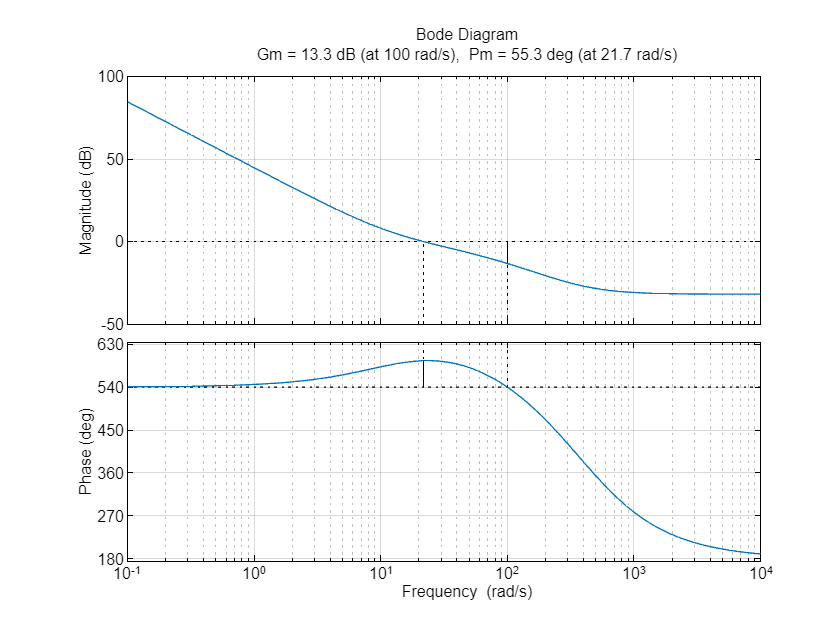

w2_crossover = 56.1; %rad/s
T2_2=1/(sqrt(b_2)*w2_crossover);
k2=1.3;
lead_ctrl2_tf_w = k2*(1+(b_2*T2_2*s))/(1+(T2_2*s));

margin(lead_ctrl2_tf_w*lead_ctrl1_tf_w*integ_ctrl_plant_tf_w,bode_plot_options);

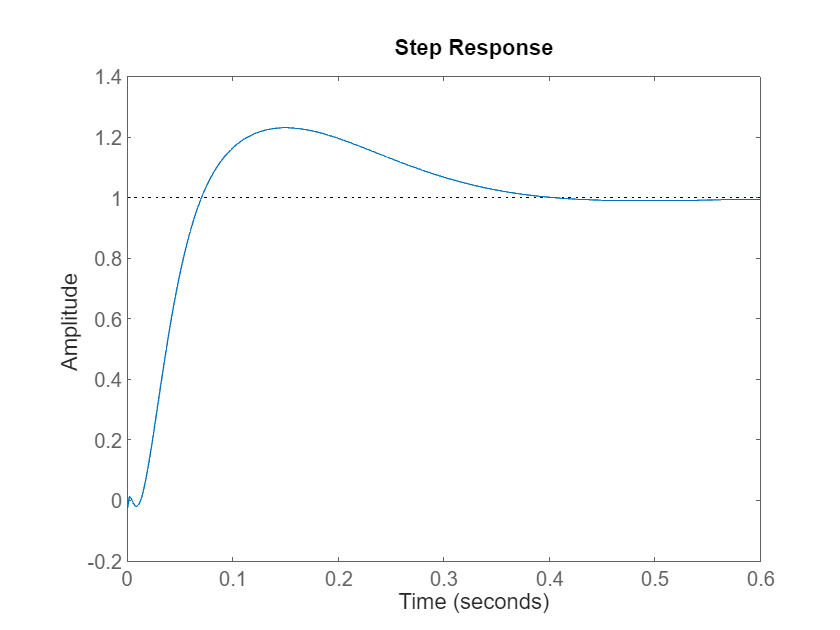

step(feedback(lead_ctrl2_tf_w*lead_ctrl1_tf_w*integ_ctrl_plant_tf_w,1));

## Inverse W transform and Final Bode

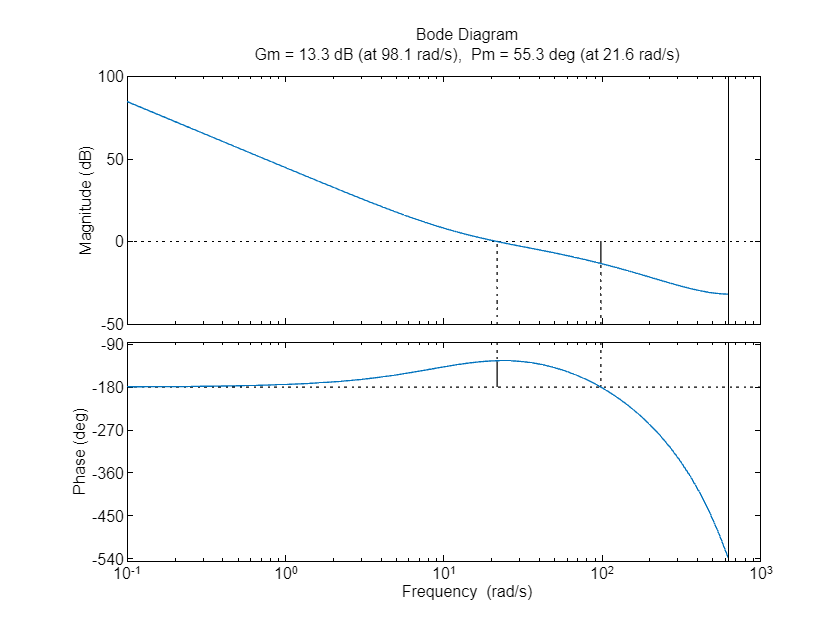

lead_ctrl1_tf_z = w_transform.w2z(lead_ctrl1_tf_w,Ts);
lead_ctrl2_tf_z = w_transform.w2z(lead_ctrl2_tf_w,Ts);
margin(lead_ctrl1_tf_z*lead_ctrl2_tf_z*integ_ctrl_z*plant_tf_z,bodeoptions);

#### Step response of Closed Loop Fully Controlled  

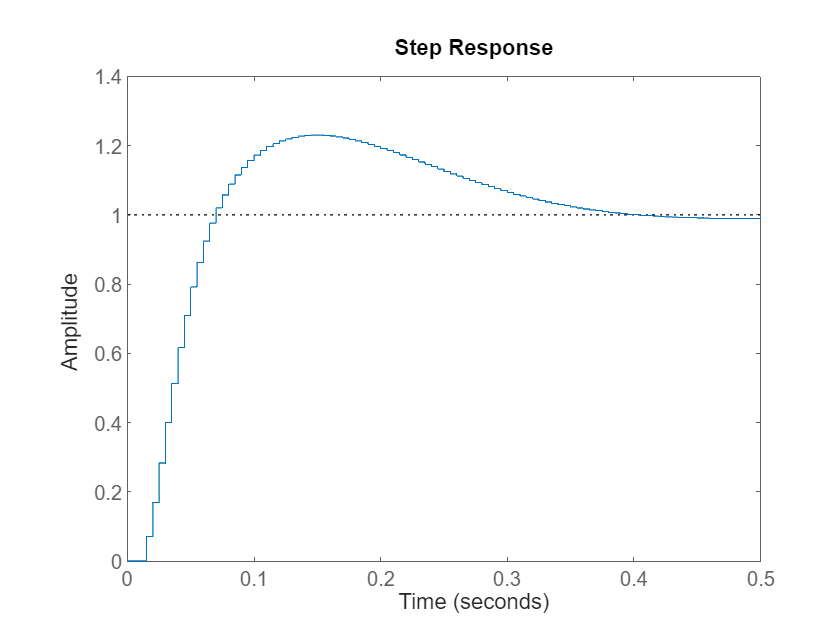

step(feedback(lead_ctrl1_tf_z*lead_ctrl2_tf_z*integ_ctrl_z*plant_tf_z,1));

## Final Controllers

final_ctrl_tf_z = lead_ctrl1_tf_z*lead_ctrl2_tf_z*integ_ctrl_z;
[num,den] = tfdata(zpk(final_ctrl_tf_z));
arrayNum = cell2mat(num);
arrayDen = cell2mat(den);
final_ctrl_tf_neg_z = tf(arrayNum,arrayDen,Ts,"variable",'z^-1');
[final_num,final_den] = tfdata(final_ctrl_tf_neg_z);
final_ctrl_num = cell2mat(final_num);
final_ctrl_den= cell2mat(final_den);
final_ctrl_tf_neg_z

final_ctrl_tf_neg_z =
 
         0.2718 z^-2 - 0.5012 z^-3 + 0.2308 z^-4
  ------------------------------------------------------
  1 - 2.416 z^-1 + 1.8 z^-2 - 0.3513 z^-3 - 0.03255 z^-4
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties
